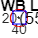

% Define initial positions for device and anchor nodes
deviceLocInitial = [50 50];  % Initial device position
nodeLocInitial = [40 41;     % Initial anchor node positions
                  62 83;
                  87 24];

% Define velocity for device (change as needed)
deviceVelocity = [0.5, 0.2];   % Velocity of the device in x and y directions

% Simulation parameters
numTimeSteps = 100;  % Number of time steps for simulation
timeStep = 0.1;      % Time step duration (adjust as needed)

% Initialize device and anchor node positions
deviceLoc = deviceLocInitial;

% Initialize actual distances and errors
actualDistances = sqrt(sum((nodeLocInitial - deviceLocInitial).^2, 2));
errors = nan(numTimeSteps, numel(actualDistances));

% Initialize plot variables
figure;
hold on;
xlabel('X Position');
ylabel('Y Position');
title('Dynamic UWB Localization');
axis tight;

% Initialize plot limits
minX = min([deviceLocInitial(1), nodeLocInitial(:, 1)']);
maxX = max([deviceLocInitial(1), nodeLocInitial(:, 1)']);
minY = min([deviceLocInitial(2), nodeLocInitial(:, 2)']);
maxY = max([deviceLocInitial(2), nodeLocInitial(:, 2)']);
margin = 5; % Margin for zooming
axis([minX-margin maxX+margin minY-margin maxY+margin]);

% Plot initial positions of device and anchor nodes
devicePlot = plot(deviceLocInitial(1), deviceLocInitial(2), 'ro', 'MarkerSize', 10, 'DisplayName', 'Device');
nodePlot = plot(nodeLocInitial(:, 1), nodeLocInitial(:, 2), 'bs', 'MarkerSize', 10, 'DisplayName', 'Anchor Nodes');

% Initialize text annotation for device coordinates
deviceText = text(deviceLocInitial(1), deviceLocInitial(2), sprintf('(%.1f, %.1f)', deviceLocInitial), 'HorizontalAlignment', 'left');

% Main simulation loop
for t = 1:numTimeSteps
    % Update device position
    deviceLoc = deviceLoc + deviceVelocity * timeStep;
    
    % Calculate predicted distances
    predictedDistances = sqrt(sum((nodeLocInitial - deviceLoc).^2, 2));
    
    % Calculate errors
    errors(t, :) = abs(actualDistances - predictedDistances)';
    
    % Update plot positions
    set(devicePlot, 'XData', deviceLoc(1), 'YData', deviceLoc(2));
    
    % Update text annotation for device coordinates
    set(deviceText, 'Position', [deviceLoc(1), deviceLoc(2)], 'String', sprintf('(%.1f, %.1f)', deviceLoc));
    
    % Draw plot
    drawnow;

    % Pause for visualization (optional)
    pause(0.1);
end


% Print errors at each step
fprintf('Errors at each step:\n');

Errors at each step:


disp(errors);

    0.0506    0.0359    0.0294
    0.1011    0.0717    0.0587
    0.1517    0.1074    0.0880
    0.2024    0.1432    0.1173
    0.2530    0.1788    0.1465
    0.3037    0.2145    0.1757
    0.3544    0.2500    0.2048
    0.4051    0.2856    0.2338
    0.4559    0.3211    0.2629
    0.5067    0.3565    0.2918
    0.5575    0.3919    0.3208
    0.6083    0.4272    0.3497
    0.6591    0.4625    0.3785
    0.7100    0.4978    0.4073
    0.7609    0.5330    0.4360
    0.8118    0.5682    0.4648
    0.8627    0.6033    0.4934
    0.9137    0.6383    0.5220
    0.9647    0.6733    0.5506
    1.0157    0.7083    0.5791
    1.0667    0.7432    0.6076
    1.1177    0.7781    0.6360
    1.1688    0.8129    0.6644
    1.2198    0.8476    0.6927
    1.2709    0.8824    0.7210
    1.3220    0.9170    0.7492
    1.3732    0.9516    0.7774
    1.4243    0.9862    0.8055
    1.4755    1.0207    0.8336
    1.5267    1.0552    0.8617
    1.5779    1.0896    0.8897
    1.6291    1.1240    0.9176
    1.68


% Calculate final location coordinates
finalDeviceLoc = deviceLoc;
fprintf('Final location coordinates: (%.1f, %.1f)\n', finalDeviceLoc);

Final location coordinates: (55.0, 52.0)
